% (C) Copyright 2020 Murilo Marques Marinho
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Murilo Marques Marinho - murilo@nml.t.u-tokyo.ac.jp

# Robot Control Basics using DQ Robotics - Part 3

## Introduction

In the last lesson, you learned how model robotic manipulators parameterized using the DH parameters. You also learned how to use a basic controller based on the pseudo-inverse of the task Jacobian.

That was an introductory exposition to robot control, and this lesson will introduce you to the concept of task-space singularities and a particular way to address them.

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

## Notation

Keep these in mind (we will also use this notation when writting papers to conferences and journals):

- ${\it \bf h} \in\mathbb{H}$: a quaternion. (Bold-face, lowercase character)

- $\underline{{\it \bf h}}\in\mathcal{H}$: a dual quaternion. (Bold-face, underlined, lowercase character)

- ${\it \bf{p}},{\it \bf{t}},\cdots\in \mathbb{H}_p$: pure quaternions. They represent points, positions, and translations. They are quaternions for which $\text{Re}\left({\it \bf h}\right)=0$.

- ${\it \bf r}\in\mathbb{S}^3$: unit quaternions. They represent orientations and rotations. They are quaternions for which $||{\it \bf h}||=1$. 

- $\underline{\it \bf x} \in$$\underline{\mathcal{S}}$: unit dual quaternions. They represent poses and pose transformations. They are dual quaternions for which $||{\it \bf h}||=1$.

- $\underline{{\it \bf l}}\in \mathcal{H}_p\cap$$\underline{\bf{\mathcal{S}}}$: a Plücker line. 

- $\underline{{\it \bf \pi}}\in \left\{ P\left(\underline{{\it \bf \pi}}\right) \in \mathbb{H}_p\right\}\cap\underline{\bf{\mathcal{S}}}$: a plane.

- $\theta,a,b,\cdots\in\mathbb{R}$: real numbers. 

- ${\it \bf q,\cdots}\in\mathbb{R}^n:$real vectors.

- ${\it \bf J}, {\it \bf A}, {\it \bf B}, \cdots \in \mathbb{R}^{m\times n}:$ real matrices.

## Robot definition

The concepts of this lesson apply to any manipulator robot. However, to have a more concrete understanding using DQ Robotics, consider the following robot that will be used in all examples in this lesson.

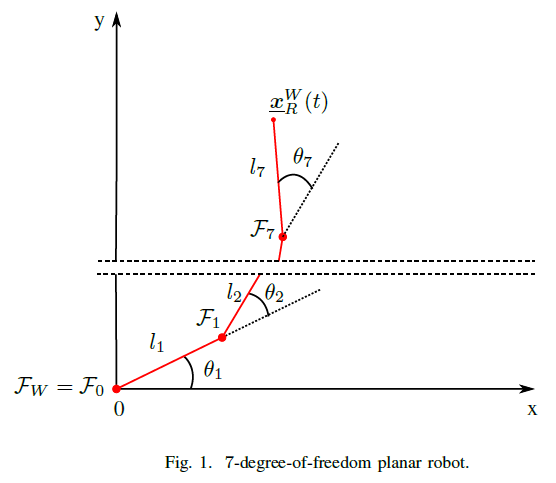

- Let the robot $R$ be a 7-DoF planar robot, as draw in Fig.1. 

- Let $\mathcal{F}_W$ be the world-reference frame. 

- Let $\underline{\it \bf{x}}_R^W(t)\triangleq\underline{\it \bf{x}}_R$ $\in$$\underline{\mathcal{S}}$ represent the pose of the *end effector*. 

- Let $R$ be composed of seven rotational joints that rotate about their z-axis, composed in the joint-space vector ${\it \bf q}\left(t\right)\triangleq{\it \bf q}=\left[\theta_{1}\ \theta_{2}\ \theta_{3}\ \theta_{4}\ \theta_{5}\ \theta_{6}\ \theta_{7}\right]^{T}$ with $\theta_{i}\left(t\right)\triangleq\theta_{i}\in\mathbb{R}$ for $i=1,2,\ldots,7$. The rotation of the reference frames of each joint coincide with the rotation of $\mathcal{F}_W$ when $\theta_{i}=0$. The length of the joints are $l_i \in$$\mathbb{R}^+-\{0\}$.

- Consider that we can freely control the joint vector ${\it \bf q}$.

This robot can be modeled by the following class.

Let us instante our robot as follows

seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

## Robot controller

The concepts of this lesson also apply for any of the task-space control types mentioned in the last lesson (and others). For us to have a concrete example for this lesson, let us define a translation controller based on the pseudo-inverse of the Jacobian with no damping.

translation_controller = DQ_PseudoinverseController(seven_dof_planar_robot);
translation_controller.set_control_objective(ControlObjective.Translation)
translation_controller.set_gain(10)
translation_controller.set_damping(0)

## Task-space singularities

One important concept when controlling a robot using its task Jacobian is the concept of task-space singularities. The task-space singularities are closely related to the linear-algebra concept of singular matrices. Let us remember a few linear-algebra concepts. 

### Matrix rank and singularities

Take as an example the $3\times3$ identity matrix


$${\it \bf I}_{3\times3}= \left[\matrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 1 & 0 }\right].$$


I3_3 = eye(3)

I3_3 =      1     0     0
     0     1     0
     0     0     1


It obviously has rank three, that is, its three rows are linearly independent.

rank(I3_3)

ans = 3

However, the following the matrix


$${\it \bf A}= \left[\matrix{0 & 0 & 1 \cr 0 & 0 & 1 \cr 0 & 1 & 0 }\right],$$


A = [0 0 1;
      0 0 1;
      0 1 0]

A =      0     0     1
     0     0     1
     0     1     0


has rank two given that its first and second row are linearly dependent. 

  rank(A)

ans = 2

A square matrix is considered singular whenever its rank is lower than its number of rows (or columns). This means that the matrix does not have an inverse.

Moreover, non-square matrices also do not have an inverse. 

Is there a way to "invert" rectangular matrices and singular matrices?

### A quick review on the SVD-based inverse for full-rank matrices

Suppose that we want to find a pseudo-inverse for any full-rank matrix ${\it \bf A}^{m\times n}, \text{rank}({\it \bf A})=m$ (which includes non-square ones). For convenience, let us restrict the examples in this lesson for matrices in which $m\leq n$ (which also conveniently fit most of the robots we will study in these lessons). 

For instance, let us work with


$${\it \bf A}= \left[\matrix{2 & 0 & 1 & 2 \cr 0 & 0 & 1 & 4 \cr 0 & 1 & 0 & 5  }\right].$$


  A = [2 0 1 2;
       0 0 1 4;
       0 1 0 5;]

A =      2     0     1     2
     0     0     1     4
     0     1     0     5


Which has rank three.

   rank(A)

ans = 3

As you might remember from your undergraduate-level courses, every real matrix can be decomposed in its singular-value decomposition (SVD) as follows


$${\it \bf A} = {\it \bf U}{\it \bf \Sigma}{\it \bf V}^T$$


where ${\it \bf U}\in\mathbb{R}^{m \times m}$ and ${\it \bf V}\in\mathbb{R}^{n \times n}$ are orthonormal matrices (i.e., they are square, full rank, and their inverses are given by ${\it \bf U}{\it \bf U}^T={\it \bf U}^T{\it \bf U}={\it \bf I}_{m \times m}$ and ${\it \bf V}{\it \bf V}^T={\it \bf V}^T{\it \bf V}={\it \bf I}_{n \times n}$). Moreover, ${\it \bf \Sigma}$ is a (rectangular) diagonal matrix composed of the singular values of the matrix given by $\sigma_i$ for $i=1,\ldots,m$, ordered from the largest singular value towards the smallest singular value. Note that singular values are always non-negative. 

**Note: All singular values of a given matrix will be non-zero when the matrix has full rank.**

Calculating this decomposition by hand can be quite complicated and time-consuming for large matrices, so we in practice resort to numerical methods. 

In MATLAB you can use the function

help svd

 svd    Singular value decomposition.
    [U,S,V] = svd(X) produces a diagonal matrix S, of the same 
    dimension as X and with nonnegative diagonal elements in
    decreasing order, and unitary matrices U and V so that
    X = U*S*V'.
 
    S = svd(X) returns a vector containing the singular values.
 
    [U,S,V] = svd(X,0) produces the "economy size"
    decomposition. If X is m-by-n with m > n, then only the
    first n columns of U are computed and S is n-by-n.
    For m <= n, svd(X,0) is equivalent to svd(X).
 
    [U,S,V] = svd(X,'econ') also produces the "economy size"
    decomposition. If X is m-by-n with m >= n, then it is
    equivalent to svd(X,0). For m < n, only the first m columns 
    of V are computed and S is m-by-m.
 
    See also svds, gsvd.

    

With it, we can get the SVD decomposition of our matrix as

[U,S,V] = svd(A);

You can verify that the orthonormal matrices follow their properties.

U*U'

ans =     1.0000   -0.0000    0.0000
   -0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


V'*V

ans =     1.0000    0.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000    0.0000
    0.0000   -0.0000    1.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000


Given that ${\it \bf \Sigma}$ always has the same dimensions of the original matrix, when the matrix is square, its corresponding ${\it \bf \Sigma}$ will be square


$${\it \bf \Sigma} = \left[ \matrix
{\sigma_1 & 0 & \cdots  & 0 \cr
0 & \sigma_2 & \dots & 0 \cr
0 & \vdots & \ddots & 0 \cr
0 & 0 & 0 & \sigma_m
 } \right]$$


When the matrix is rectangular, its corresponding ${\it \bf \Sigma}$ will be rectangular, for instance


$${\it \bf \Sigma} = \left[ \matrix
{\sigma_1 & 0 & \cdots  & 0 & 0\cr
0 & \sigma_2 & \dots & 0 & 0\cr
0 & \vdots & \ddots & 0 & 0\cr
0 & 0 & 0 & \sigma_m & 0
 } \right]$$


S

S =     6.8394         0         0         0
         0    2.0939         0         0
         0         0    0.9158         0


With these properties, a right pseudo-inverse can be defined for any matrix for which all singular values are non-zero. The right pseudo-inverse is 

${\it \bf A}^\dagger \triangleq{\it \bf V}{\it \bf \Sigma}^{\text{inv}} {\it \bf U}^T$.

where ${\it \bf \Sigma}^{\text{inv}}$ is a compatible matrix where we use the reciprocate of the singular values. For example, for a square matrix we have


$${\it \bf \Sigma}^{inv} \triangleq \left[ \matrix
{\frac{1}{\sigma_1} & 0 & \cdots  & 0 \cr
0 & \frac{1}{\sigma_2} & \dots & 0 \cr
0 & \vdots & \ddots & 0 \cr
0 & 0 & 0 & \frac{1}{\sigma_m}
 } \right]$$


and for a rectangular matrix


$${\it \bf \Sigma}^{inv}  \triangleq \left[ \matrix
{\frac{1}{\sigma_1} & 0 & \cdots  & 0\cr
0 & \frac{1}{\sigma_2} & \dots & 0 \cr
0 & \vdots & \ddots & 0 \cr
0 & 0 & 0 & \frac{1}{\sigma_m} \cr
0 & 0 & 0 & 0
 } \right]$$


S_inv = [1.0/S(1,1) 0          0;
         0          1.0/S(2,2) 0;
         0          0          1.0/S(3,3);
         0          0          0 ;]

S_inv =     0.1462         0         0
         0    0.4776         0
         0         0    1.0920
         0         0         0


Then, we find that


$${\it \bf \Sigma} {\it \bf \Sigma}^{inv}= {\it \bf I}_{m\times m}.$$


S*S_inv

ans =      1     0     0
     0     1     0
     0     0     1


Therefore, we find that


$${\it \bf A}{\it \bf A}^\dagger= {\it \bf U}{\it \bf \Sigma}{\it \bf V}^T{\it \bf V}{\it \bf \Sigma}^{\text{inv}} {\it \bf U}^T$$



$${\it \bf A}{\it \bf A}^\dagger= {\it \bf I}_{m\times m} \:\text{(see Bonus Homework 1)}$$


A_dagger = V*S_inv*U';
A*A_dagger

ans =     1.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000
   -0.0000    0.0000    1.0000


This inverse has several interesting properties that we will discuss when they are needed.

### A quick review on the SVD-based inverse for singular matrices

In practice, we want our algorithm to be able to invert even singular matrices. Let ${\it \bf B}^{m\times n}$ be such that $\text{rank}({\it \bf B})=r< m$. For convenience, let us restrict the examples for matrices in which $m\leq n$. For instance, let us use

${\it \bf B}= \left[\matrix{2 & 0 & 1 & 2 \cr 0 & 0 & 1 & 4 \cr 2 & 0 & 1 & 2  }\right]$, 

B = [2 0 1 2;
     0 0 1 4;
     2 0 1 2;]

B =      2     0     1     2
     0     0     1     4
     2     0     1     2


that has rank two.

rank(B)

ans = 2

Similarly to full-rank matrices, the SVD-based inverse can also be used for singular matrices. In our case,  $m-r$ singular values will be zero. 

**Note: A matrix is singular when at least one of its singular values is zero.**

The null singular values are ignored when we calculate the "inverse" of the matrix that holds the singular values, as follows


$${\it \bf \Sigma}^{inv} = \left[ \matrix
{\frac{1}{\sigma_1} & 0 & \cdots  & 0 & \cdots & 0\cr
0 & \frac{1}{\sigma_2} & \dots & 0 & \cdots & 0 \cr
0 & \vdots & \ddots & 0 & \cdots & 0 \cr
0 & 0 & 0 & \frac{1}{\sigma_r} & \cdots & 0 \cr
\vdots & \vdots & \vdots & \vdots  & \ddots & 0\cr
0 & 0 & 0 & 0 & \cdots & 0
 } \right].$$


This means that when the pseudo-inverse is applied, the result will be "as close as possible" to the identity. The meaning of "as close as possible" will be somewhat fuzzy for now, but it will get clearer as the lessons progress. Just understand that if $\text{rank}({\it \bf B})<m$, there is no matrix ${\it \bf B}^{inv}$ such that ${\it \bf B}{\it \bf B}^{inv}={\it \bf I}_{m\times m}$. We ***have*** to compromise.

MATLAB has an implementation for the SVD-based inverse (and you already used it in lesson 5). 

help pinv

 pinv   Pseudoinverse.
    X = pinv(A) produces a matrix X of the same dimensions
    as A' so that A*X*A = A, X*A*X = X and A*X and X*A
    are Hermitian. The computation is based on SVD(A) and any
    singular values less than a tolerance are treated as zero.
 
    pinv(A,TOL) treats all singular values of A that are less than TOL as
    zero. By default, TOL = max(size(A)) * eps(norm(A)).
 
    Class support for input A: 
       float: double, single
 
    See also rank.

    Documentation for pinv
    Other functions named pinv



In our case, we can calculate for ${\it \bf B}$. Using this pseudo-inverse will not result in the identity because $\text{rank}({\it \bf B})\leq m$, as follows

B*pinv(B)

ans =     0.5000   -0.0000    0.5000
    0.0000    1.0000    0.0000
    0.5000   -0.0000    0.5000


Note that the same function it can also be used for ${\it \bf A}$. Using this pseudo-inverse will result in the identity because $\text{rank}({\it \bf A})=m$, as follows

A*pinv(A)

ans =     1.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000
   -0.0000    0.0000    1.0000


### So, after all this, what are task-space singularities, then?

Task-space singularities are postures, that is, combinations of joint values for which the rank of the task Jacobian is smaller than the dimension of the task-space. 

**Note: A task-space singulary depends on the definition of task-space.**

To make that understanding somewhat more concrete, let us go back to our example, where we are controlling the translation of the end effector of our 7 degrees-of-freedom planar-robot. 

If we define our task space as the 3D translation, that is the translation in the $x-$axis, $y-$axis, and $z-$axis, then all robot postures will be singular because the $z-$axis translation of our planar robot cannot be controlled. The maximum rank of the translation Jacobian of our planar robot will always be less or equal to two.

q = randn(1,7);
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q); 
Jt = seven_dof_planar_robot.translation_jacobian(Jx,x);
rank(Jt)

ans = 2

If we define our task-space as the 2D translation of the $x-$axis and the $y-$axis, then most of the robot postures will not be singular. However, some of them will still be. 

For instance, when all links are aligned at $\theta_i=0\$ $\forall
$ $i$, 

q = zeros(1,7);
x = seven_dof_planar_robot.fkm(q);
Jx = seven_dof_planar_robot.pose_jacobian(q); 
Jt = seven_dof_planar_robot.translation_jacobian(Jx,x);
rank(Jt)

ans = 1

### I see, but what is the problem?

The problem are not the task-space singularities themselves, but in the transition between singular and non-singular postures. Remember that the SVD-based inverse is based on 


$${\it \bf \Sigma}^{inv} = \left[ \matrix
{\frac{1}{\sigma_1} & 0 & \cdots  & 0 & \cdots & 0\cr
0 & \frac{1}{\sigma_2} & \dots & 0 & \cdots & 0 \cr
0 & \vdots & \ddots & 0 & \cdots & 0 \cr
0 & 0 & 0 & \frac{1}{\sigma_r} & \cdots & 0 \cr
\vdots & \vdots & \vdots & \vdots  & \ddots & 0\cr
0 & 0 & 0 & 0 & \cdots & 0
 } \right].$$


which means that we take the reciprocate of the singular values. The reciprocate of the singular values can be very large numbers when the singular values are small. 

This causes the SVD-based pseudo-inverse to output unfeasible velocities to the manipulator, that can be dangerous for the robot itself (it can break), and it can damage people/things in its vincinity.

First, consider a non-singular posture for our example manipulator, such as $\theta_i=\pi/2$ $\forall
$ $i$. Calculate the next iteration of our controller for the reference ${\it \bf t}_d = 7\hat{\jmath}$.

td = 7*j_;
q = (pi/2.0)*ones(1,7);
u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
max(u)

ans = 15.0000

which is a resonable maximum joint velocity.

Now, let us try that in the vincinity of a singularity. For instance, back to our example, consider an initial posture $\theta_i=0.00001\$ $\forall
$ $i$

td = 7*j_;
q = 0.00001*ones(1,7);
translation_controller.compute_setpoint_control_signal(q,vec4(td));
u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
max(u)

ans = 3.8234e+05

which is a completely unreasonable maximum joint velocity. In fact, the closer you are to the singularity, the worse the behavior will be.

For instance, 

Now, let us try that in the vincinity of a singularity. For instance, back to our example, consider an initial posture $\theta_i=0.000000001\$ $\forall
$ $i$

td = 7*j_;
q = 0.000000001*ones(1,7);
translation_controller.compute_setpoint_control_signal(q,vec4(td));
u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
max(u)

ans = 3.8235e+09

which is a even more unreasonable maximum joint velocity.

### Ok, I still don't understand. What is the problem?

Let us control our example robot from $\theta_i=0$ $\forall
$ $i$ to ${\it \bf t}_d = 7\hat{\jmath}$ using the SVD-based pseudo-inverse. 

This simulation will be run in slow motion and so that you can see the weird behavior of the robot near the singularity. 

Instead of moving in a smooth manner, the robot teleports to a far-away posture contorts itself because of the unreasonably high-velocities caused by the SVD-based pseudo-inverse. Using DQ Robotics, the SVD-based inverse will be used if the damping factor is zero for a "DQ_PseudoinverseController".

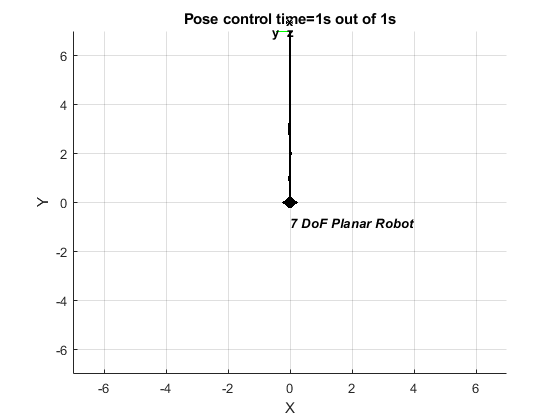

clear all;
close all;
include_namespace_dq;

% Define the robot
seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

% Define the controller
translation_controller = DQ_PseudoinverseController(seven_dof_planar_robot);
translation_controller.set_control_objective(ControlObjective.Translation)
translation_controller.set_gain(10)
translation_controller.set_damping(0)

% Desired translation (pure quaternion)
td = 7*j_;
% Sampling time [s]
tau = 0.01; 
% Simulation time [s]
final_time = 1;
% Translation controller loop.
q = zeros(7,1);
stored_u = [];

for time=0:tau:final_time
    % Get the next control signal [rad/s]
    u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
    
    % Move the robot
    q = q + u*tau;
    
    % Store data
    stored_u = [stored_u u];
    
    % Plot
    % Plot the robot
    plot(seven_dof_planar_robot,q);
    title(['Pose control' ' time=' num2str(time) 's out of ' num2str(final_time) 's'])
    % Plot the desired pose
    hold on
    plot3(td.q(2),td.q(3),td.q(4));
    hold off
    % [For animations only]
    drawnow; % [For animations only] Ask MATLAB to draw the plot now
    pause(0.5)
end

The issue can be clearly seen when we plot the first 0.1 sec of the controller output. In the first control step, there is no issue because the robot is singular posture. When the robot moves a bit away from the singular posture, the next control signal "explodes".

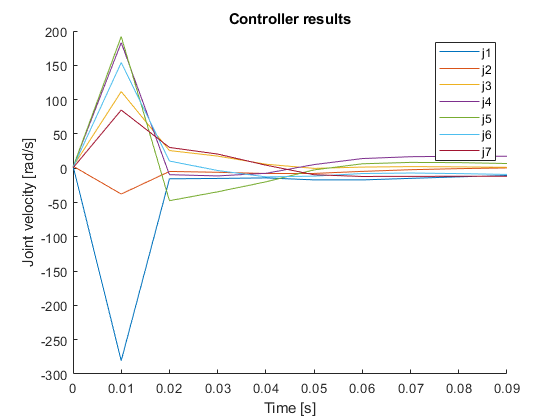

plot_u(stored_u,0:tau:final_time,10)

There are three main points that need to be understood about task-space singularities.

- **singularities have to be addressed so that the robot does not damage itself and its vincinity,**

- **singularities are a manifestation of mechanical phenomena related to the definition of the task-space. They do not mean the mathematic model is broken, they simply and correctly represent a mechanical issue.**

- **singularities usually occur when joints are aligned, but predicting singular configurations for robots with a large number of degrees-of-freedom is not trivial.**

## Damped pseudo-inverse

The damped pseudo-inverse is an interesting alternative to the SVD-based inverse that gives the system some robustness to task-space singularities. The main idea is to use the following pseudo-inverse for any (possibly singular) matrix ${\it \bf B}\in\mathbb{R}^{m\times n}$, called the *damped-pseudo inverse*


$${\it \bf B}^+\triangleq\left({\it \bf B}^T{\it \bf B}+\lambda{\it \bf I}\right)^{-1}{\it \bf B}^T$$


where $\lambda\in\mathbb{R}^{+}-\{0\}$ is the damping factor. The meaning of this damping factor will become clearer in the next lesson, but for now it suffices to know that given that


$$\left({\it \bf B}^T{\it \bf B}+\lambda{\it \bf I}\right)^{-1}\:\text{(Bonus Homework 2)}$$


always exists, regular inversion algorithms can be used to calculate the damped pseudo-inverse. Using MATLAB, this would mean, for instance

B = [2 0 1 2;
     0 0 1 4;
     2 0 1 2;]

B =      2     0     1     2
     0     0     1     4
     2     0     1     2


lambda = 0.01;
B_damped_inverse = inv(B'*B + lambda*eye(4))

B_damped_inverse =     5.7292         0  -22.1960    5.4867
         0  100.0000         0         0
  -22.1960         0   88.8951  -22.2237
    5.4867         0  -22.2237    5.6184


B*B_damped_inverse

ans =     0.2357         0    0.0555   -0.0137
   -0.2494         0    0.0001    0.2497
    0.2357         0    0.0555   -0.0137


### Damped pseudo-inverse and singularity robustness

In the point-of-view of Jacobian-based robot control, the damping factor lets us balance the trade-off between optimal joint velocities (in the sense of task error reduction) and joint velocity norm.

If you choose a larger damping factor, the robot will be more robust to task-space singularities, but it might take longer to reach the desired task-space value. As you lower the damping factor, the behavior gets closer to the SVD-based pseudo-inverse. If the damping is too low, the joint velocities will also be dangerous when the robot is close to singular configurations.

To show a concrete example of the damped pseudo-inverse in action, let us copy and paste our prior example. After that, we change only the damping factor and see its effect on robot control.

clear all;
close all;
include_namespace_dq;

% Define the robot
seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

% Define the controller
translation_controller = DQ_PseudoinverseController(seven_dof_planar_robot);
translation_controller.set_control_objective(ControlObjective.Translation);
translation_controller.set_gain(10);

damping = 1

damping = 1

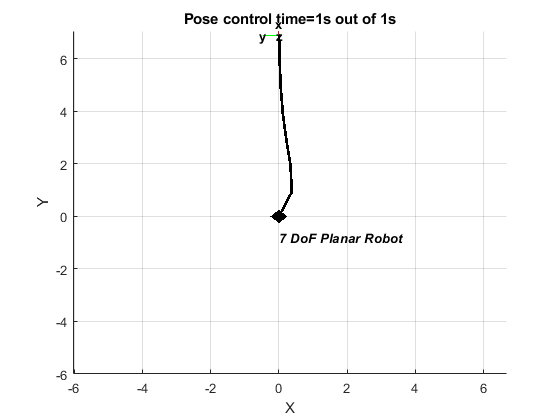

translation_controller.set_damping(damping)

% Desired translation (pure quaternion)
td = 7*j_;
% Sampling time [s]
tau = 0.01; 
% Simulation time [s]
final_time = 1;
% Translation controller loop.
q = zeros(7,1);
stored_u = [];

for time=0:tau:final_time
    % Get the next control signal [rad/s]
    u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
    
    % Move the robot
    q = q + u*tau;
    
    % Store data
    stored_u = [stored_u u];
    
    % Plot
    % Plot the robot
    plot(seven_dof_planar_robot,q);
    title(['Pose control' ' time=' num2str(time) 's out of ' num2str(final_time) 's'])
    % Plot the desired pose
    hold on
    plot3(td.q(2),td.q(3),td.q(4));
    hold off
    % [For animations only]
    drawnow; % [For animations only] Ask MATLAB to draw the plot now
    pause(0.5)
end

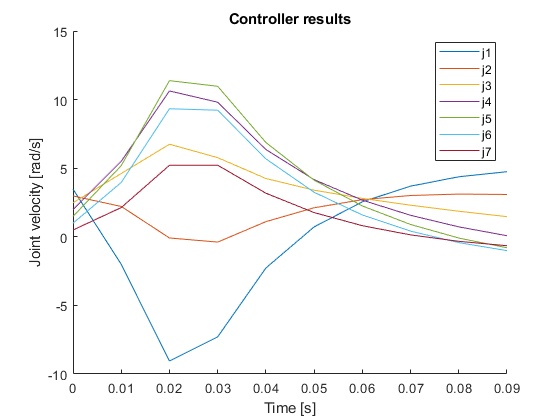

 
plot_u(stored_u,0:tau:final_time,10)

As you can also see from the plotted values, the robot safely moved towards the goal without excessive joint velocities when $\lambda=1$.

# Homework

Consider the 7-DoF planar robot used during this lesson. Consider the following damping values $\lambda\in\left\{0.001,0.01,0.1,0.2,0.3,0.4,0.5,1\right\}$. 

**Condition 1: **$\theta_i=0$ $\forall
$ $i$ to ${\it \bf t}_d = 7\hat{\jmath}$. $\eta=10, \tau=0.01$

Create a file called [seven_dof_robot_damping_comparison_singular.m] that does the following

- Run the following eight controllers: one SVD-based pseudoinverse translation controller AND seven damped-pseudo inverse translation controllers, each one with one of the damping values defined above. Store their ***task-space error norm*** and their ***controller output error norm***.

- Using subplot with one row and two columns: plot on the left subplot the ***task-space error norm *** for all controllers, so that they can be compared. On the right subplot, plot the ***controller output error norm ***for all controllers so that they can be compared*.*

**Condition 2: **$\theta_i=\pi/12$ $\forall
$ $i$ to ${\it \bf t}_d = 7\hat{\jmath}$. $\eta=10, \tau=0.01$

Create a file called [seven_dof_robot_damping_comparison.m] that does the following

- Run the following eight controllers: one SVD-based pseudoinverse translation controller AND seven damped-pseudo inverse translation controllers, each one with one of the damping values defined above. Store their ***task-space error norm*** and their ***controller output error norm***.

- Using subplot with one row and two columns: plot on the left subplot the ***task-space error norm *** for all controllers, so that they can be compared. On the right subplot, plot the ***controller output error norm ***for all controllers so that they can be compared*.*

# *Bonus Homework*

Do the following on pen-and-paper or in your favorite text editor.

- Show that ${\it \bf A}{\it \bf A}^\dagger= {\it \bf U}{\it \bf \Sigma}{\it \bf V}^T{\it \bf V}{\it \bf \Sigma}^{\text{inv}} {\it \bf U}^T={\it \bf I}_{m\times m}$ for any matrix ${\it \bf A}^{m\times n}, \text{rank}({\it \bf A})=m$, $m\leq n$, with other variables as defined in this lesson.

- Show that $\left({\it \bf B}^T{\it \bf B}+\lambda{\it \bf I}\right)$ is always invertible, for any matrix ${\it \bf B}^{m\times n}, \text{rank}({\it \bf B})<m$, $m\leq n$, with other variables as defined in this lesson.